# **Численные методы в СПб АУ РАН - Часть 2**

## **Задание по практике №5**

Кузьмичев Артём, 4 курс

## **№10 (алгоритмы и программы к разделу 9.5)**

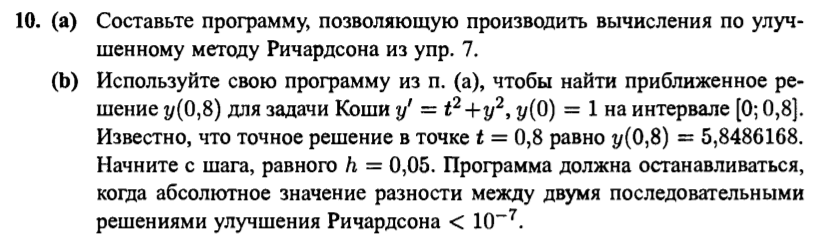

Упражнение 7 базируется на Лемме 7.1 раздела 7.3

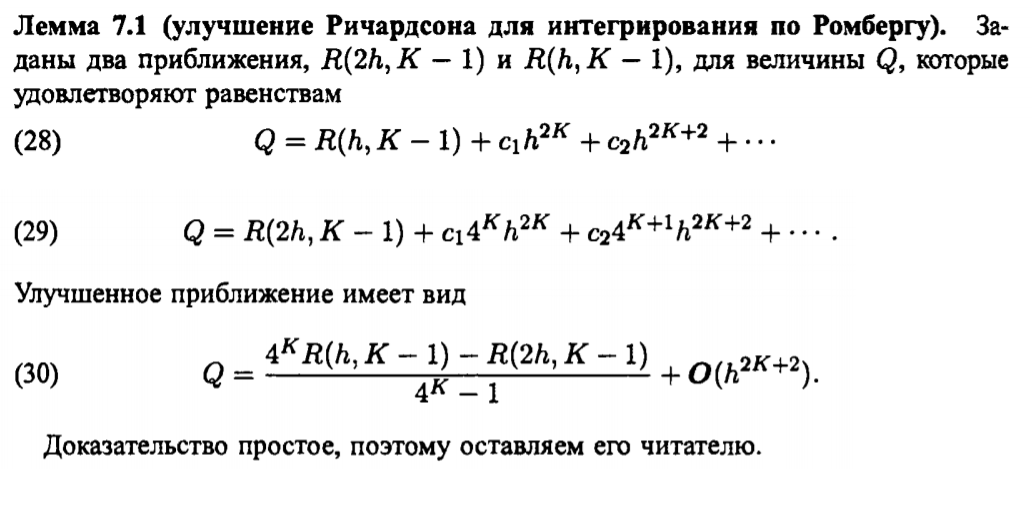

Само упражнение 7

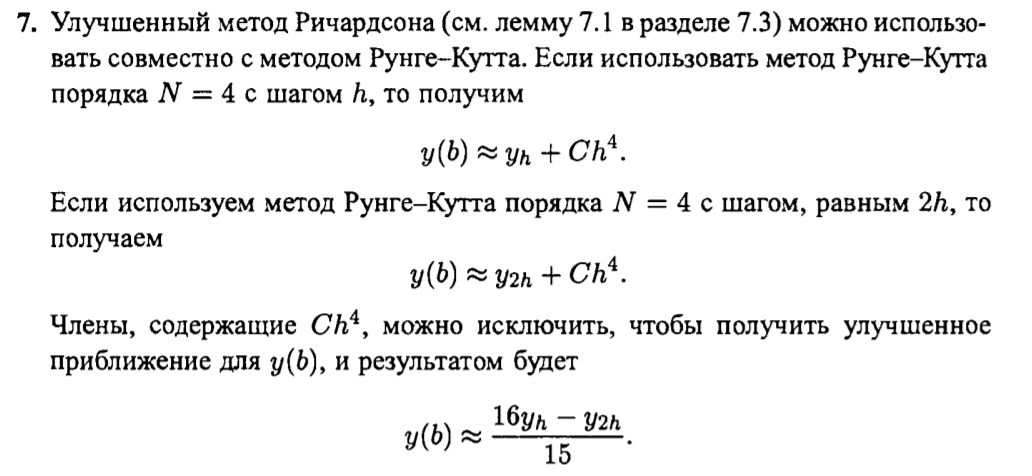

## Задача Коши

Рассмотрим задачу Коши $y^{\prime } =t^2 +y^2$ на отрезке $\left\lbrack 0;0\ldotp 8\right\rbrack$с начальным условием $y\left(0\right)=1$

syms f(t,y)
f(t,y) = y^2+t^2;
y0 = 1;
a = 0;
b = 0.8;
h = 0.05;

### Точное решение

Используем встроенную функцию *dsolve* для точного решения:

syms y(t)
eqn = diff(y,t) == f(t,y);
cond = y(0) == y0;
yExact(t) = dsolve(eqn,cond)

$$yExact(t) = \begin{array}{l} -\frac{t\,\left(\pi \,\sigma_{2}-\sigma_{1}\,\sigma_{2}+\sigma_{1}\,Y_{-\frac{3}{4}}\left(\frac{t^{2}}{2}\right)\right)}{\pi \,\sigma_{3}-\sigma_{1}\,\sigma_{3}+\sigma_{1}\,Y_{\frac{1}{4}}\left(\frac{t^{2}}{2}\right)}\\ \mathrm{where}\\ \sigma_{1}={\Gamma (\frac{3}{4})}^{2}\\ \sigma_{2}=J_{-\frac{3}{4}}\left(\frac{t^{2}}{2}\right)\\ \sigma_{3}=J_{\frac{1}{4}}\left(\frac{t^{2}}{2}\right) \end{array}$$

Получившееся выражение громоздкое, тем не менее, всё равно позволяет точно получить значение решения на правой границе рассматриваемого отрезка (8 значащих цифр)

digitsprecision = 8;
ybExact = vpa(yExact(b),digitsprecision)

$$ybExact = 5.8486168$$

что согласуется с данной в условии задания информацией:

### Метод Рунге-Кутта

Применим алгоритм Рунге-Кутта порядка $N=4$ для решения дифференциального уравнения $y^{\prime } =f\left(t,y\right)$ (*Описание функции rk4 в Приложении*)

R1 = rk4(f,a,b,y0,h);
T1 = R1(:,1);
Y1 = R1(:,2);

И повторим алгоритм с шагом, в два раза больше предыдущего:

R2 = rk4(f,a,b,y0,2*h); 
T2 = R2(:,1);
Y2 = R2(:,2);

Построим получившиеся приближённые решения на графике

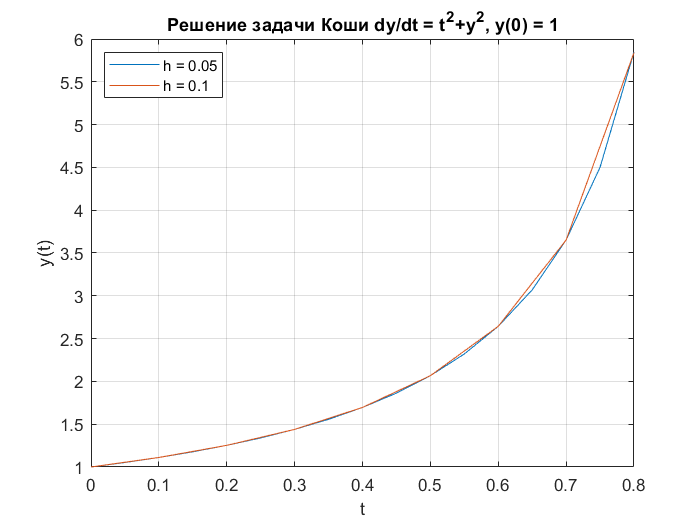

plot(T1,Y1)
title('Решение задачи Коши dy/dt = t^2+y^2, y(0) = 1');
xlabel('t');
ylabel('y(t)');
grid on
hold on
plot(T2,Y2);
legend('h = 0.05','h = 0.1',"Location","northwest")

### Улучшение Ричардсона

Чтобы применить улучшенный метод Ричардсона, воспользуеся формулой для искомого приближения:


$$y\left(b\right)\approx \frac{{16y}_h \left(b\right)-y_{2h} \left(b\right)}{15}$$


Так как $b=0\ldotp 8$, получившееся приближение для значения $y\left(0\ldotp 8\right)$

yb =  (16 * Y1(end) - Y2(end))/15;
vpa(yb,digitsprecision)

$$ans = 5.8485189$$

ybExact

$$ybExact = 5.8486168$$

Как видим, разница невелика уже даже для такого приближения. Но задание требует уменьшать шаг, пока разница между последовательными приближениями улучшения Ричардсона не достигнет $\varepsilon ={10}^{-7}$

### Метод Ричардсона-Рунге-Кутта

eps = 10e-7;

ybprev = 0;
ybi = yb;
hi = h;
i = 1;
while abs(ybi-ybprev)>eps
    ybprev = ybi;
    hi = hi/2; %делим шаг пополам каждую итерацию
    R1i = rk4(f,a,b,y0,hi);
    R2i = rk4(f,a,b,y0,2*hi);
    ybi =  (16 * R1i(end,2) - R2i(end,2))/15;
    fprintf('Шаг %d: h = %f. Значение приближения: %8.7f \n',i, hi, ybi);
    i = i + 1;
end

Шаг 1: h = 0.025000. Значение приближения: 5.8486147 
Шаг 2: h = 0.012500. Значение приближения: 5.8486168 
Шаг 3: h = 0.006250. Значение приближения: 5.8486168 


Величина $y\left(b\right)$, вычисляемая приближённо, достаточно быстро сошлась к точному значению

## Приложение

#### Определение функции, осуществляющей алгоритм Рунге-Кутта для N=4

function R = rk4(f,a,b,ya,h)
%Вход   -   f       - функция
%       -   a и b   - границы интервала
%       -   ya      - начальное условие
%       -   h       - величина шага
%Выход  -   R[T',Y']- где T - вектор абсцисс, Y - вектор ординат

M = floor((b-a)/h);
T=zeros(1,M+1);
Y=zeros(1,M+1);
T=a:h:b;
Y(1)=ya;

for j=1:M
    k1=h*f(T(j),Y(j)); 
    k2=h*f(T(j)+h/2,Y(j)+k1/2); 
    k3=h*f(T(j)+h/2,Y(j)+k2/2); 
    k4=h*f(T(j)+h,Y(j)+k3); 
    
    Y(j+1)=Y(j)+(k1+2*k2+2*k3+k4)/6;
end

R = [T' Y'];
end